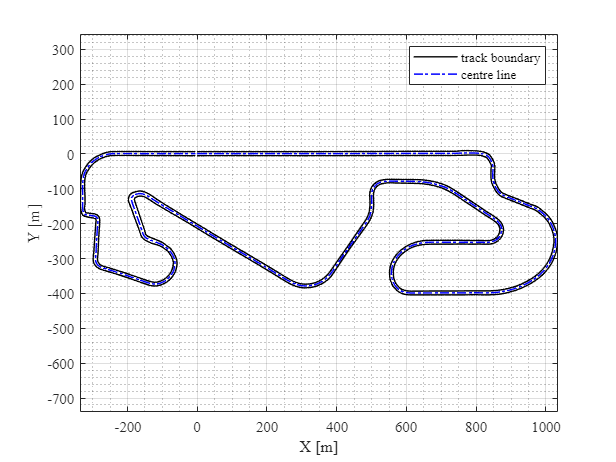

clear, clc

track_name = char("Catalunya");

track_table = readtable(['tracks\' track_name '.csv'], 'PreserveVariableNames',true);

track = table2array(track_table);

[track_bnd_r, track_bnd_l] = calc_track_bnd(track);


figure
plot(track_bnd_r(:,1),track_bnd_r(:,2),'k'), hold on, grid on
plot(track_bnd_l(:,1),track_bnd_l(:,2),'k')
plot(track(:,1),track(:,2),'b-.')
axis equal
xlabel('X [m]'), ylabel('Y [m]'), legend('track boundary','','centre line')

angle_start_global = 0;

theta = angle_start_global - atan2((track(2,2)-track(1,2)),(track(2,1)-track(1,1)));
track_rotated = calc_track_rotated(track,theta);

[track_bnd_r, track_bnd_l] = calc_track_bnd(track_rotated);


figure
plot(track_bnd_r(:,1),track_bnd_r(:,2),'k'), hold on, grid on
plot(track_bnd_l(:,1),track_bnd_l(:,2),'k')
plot(track_rotated(:,1),track_rotated(:,2),'b-.')
axis equal
xlabel('X [m]'), ylabel('Y [m]'), legend('track boundary','','centre line')

track_rotated = array2table(track_rotated);
track_rotated.Properties.VariableNames = {'x','y','wr','wl'};
writetable(track_rotated,['tracks/' track_name '.csv'])

